# HW - 08

## Q1

dt = 0.5;
xa = 0.045;
A = [0 1 0 0; 0 0 0 -xa; 0 0 0 1; 0 xa 0 0];
Fa = expm(A*dt)

Fa =     1.0000    0.5000         0   -0.0056
         0    0.9997         0   -0.0225
         0    0.0056    1.0000    0.5000
         0    0.0225         0    0.9997


xb = -0.045;
B = [0 1 0 0; 0 0 0 -xb; 0 0 0 1; 0 xb 0 0];
Fb = expm(B*dt)

Fb =     1.0000    0.5000         0    0.0056
         0    0.9997         0    0.0225
         0   -0.0056    1.0000    0.5000
         0   -0.0225         0    0.9997


gammaA = [0 0; 1 0; 0 0; 0 1];
gammaB = [0 0; 1 0; 0 0; 0 1];

qw = 10;
W = qw * [2 0.05; 0.05 0.5];
Z_a = dt * [-A gammaA*W*(gammaA)'; zeros(4,4) A'];
eZ_a = expm(Z_a);

Qa = eZ_a(5:8,5:8)' * eZ_a(1:4,5:8)

Qa =     0.8329    2.4983    0.0261    0.0953
    2.4983    9.9931    0.0719    0.3343
    0.0261    0.0719    0.2087    0.6266
    0.0953    0.3343    0.6266    2.5069


Z_b = dt * [-B gammaB*W*(gammaB)'; zeros(4,4) B'];
eZ_b = expm(Z_b);

Qb = eZ_b(5:8,5:8)' * eZ_b(1:4,5:8)

Qb =     0.8336    2.5011    0.0156    0.0297
    2.5011   10.0044    0.0531    0.1656
    0.0156    0.0531    0.2080    0.6238
    0.0297    0.1656    0.6238    2.4956


## Q2. A)

rng(100)
H = [1 0 0 0; 0 0 1 0];
Ra = [20 0.05; 0.05 20];

y_all = [];
for n = 1:201
    y = H*xasingle_truth(:,n) + (mvnrnd(zeros(2,1),Ra))';
    y_all = [y_all,y];
end

y_all;
y_100 = y_all(:,2:101)

y_100 = 1.0e+03 *

    0.1452    0.1743    0.2170    0.2514    0.2855    0.3296    0.3775    0.4227    0.4642    0.5197    0.5513    0.5925    0.6469    0.6904    0.7288    0.7748    0.8377    0.8825    0.9338    0.9787    1.0263    1.0853    1.1325    1.1919    1.2390    1.2894    1.3387    1.3915    1.4514    1.5089    1.5674    1.6192    1.6670    1.7175    1.7698    1.8376    1.8824    1.9203    1.9810    2.0322    2.0802    2.1311    2.1720    2.2198    2.2582    2.3066    2.3460    2.3821    2.4314    2.4692
    0.0728    0.0327   -0.0146   -0.0379   -0.0844   -0.1022   -0.1499   -0.1856   -0.2088   -0.2516   -0.2841   -0.3200   -0.3537   -0.3746   -0.4070   -0.4321   -0.4677   -0.4866   -0.5119   -0.5472   -0.5591   -0.5829   -0.5999   -0.6151   -0.6391   -0.6603   -0.6775   -0.6882   -0.7011   -0.7172   -0.7188   -0.7351   -0.7488   -0.7554   -0.7539   -0.7617   -0.7693   -0.7710   -0.7778   -0.7670   -0.7766   -0.7684   -0.7662   -0.7673   -0.7601   -0.7508   -0.7439   -0.7364

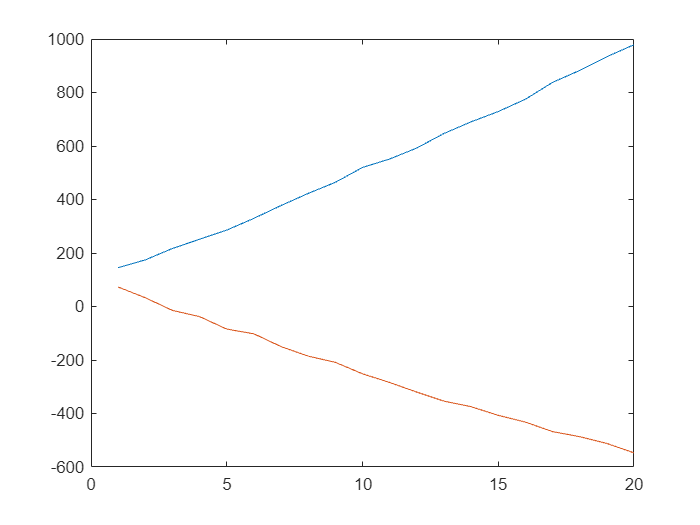

y_20 = y_all(:,2:21);
t = 1:20;
plot (t,y_20)

## Q2. B)

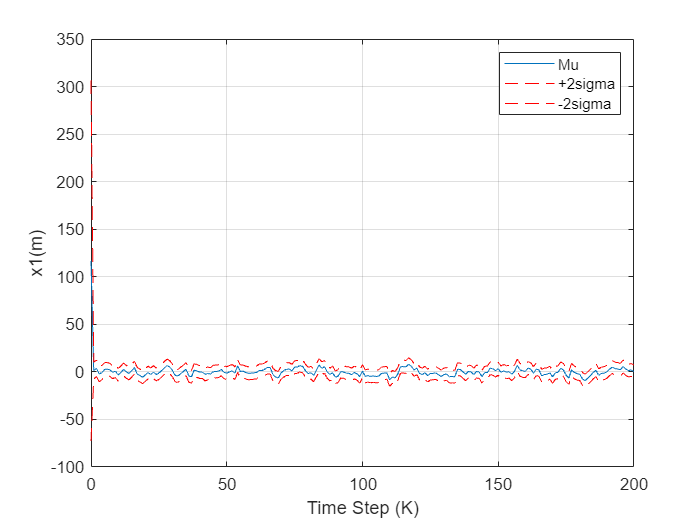

A = [0 1 0 0; 0 0 0 -xa; 0 0 0 1; 0 xa 0 0];
Fa = expm(A*dt);
H = [1 0 0 0; 0 0 1 0];
Ra = [20 0.05; 0.05 20];
Hall = repmat(H,201,1);
Rall = [];

y_all;

for n = 1:201
    Ra = [20 0.05; 0.05 20];
    Rall = blkdiag(Rall,Ra);
end
Rall;

% Kalman filtering
Mua0 = [0; 85*cos(pi/4); 0; -85*sin(pi/4)];
xall = zeros(4,201);
xall(:,1) = Mua0;
v = [10 2 10 2];
Pa0 = 900 * diag(v);
Pall = zeros(4,200);
Pall(:,1) = 900*[10;2;10;2];

for k = 1:200
    % KF Time update
    xall(:,k+1) = Fa*xall(:,k);
    Pa0 = Fa*Pa0*Fa'+ Qa;
    Kk = Pa0*H'*inv(H*Pa0*H' + Ra);
    % KF Measurement update
    xall(:,k+1) = xall(:,k+1) + Kk*(y_all(:,k+1)-H*xall(:,k+1));
    Pa0 = (eye(4,4) - Kk*H)*Pa0;
    Pall(:,k+1) = diag(Pa0);
end

xall;
Pall;
x_err = xasingle_truth - xall;
sigma = sqrt(Pall);
sigma2p = x_err + 2*sigma;
sigma2n = x_err - 2*sigma;

time = 0:200;
plot(time,x_err(1,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p(1,:),'r--'),grid on
plot(time,sigma2n(1,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

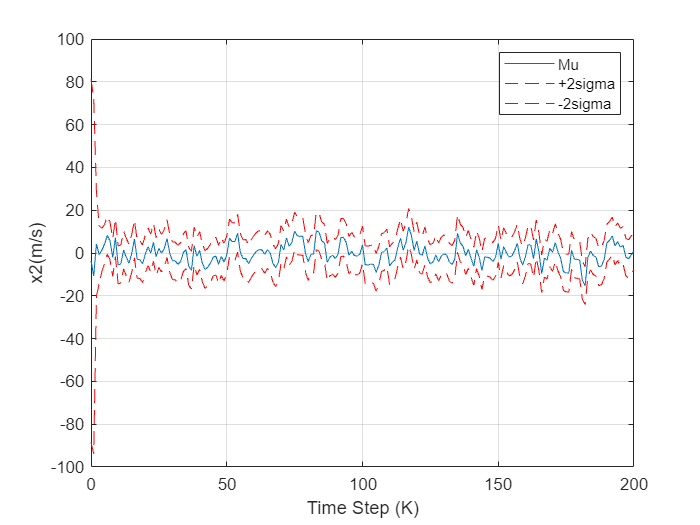

plot(time,x_err(2,:)),grid on,ylabel('x2(m/s)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p(2,:),'r--'),grid on
plot(time,sigma2n(2,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

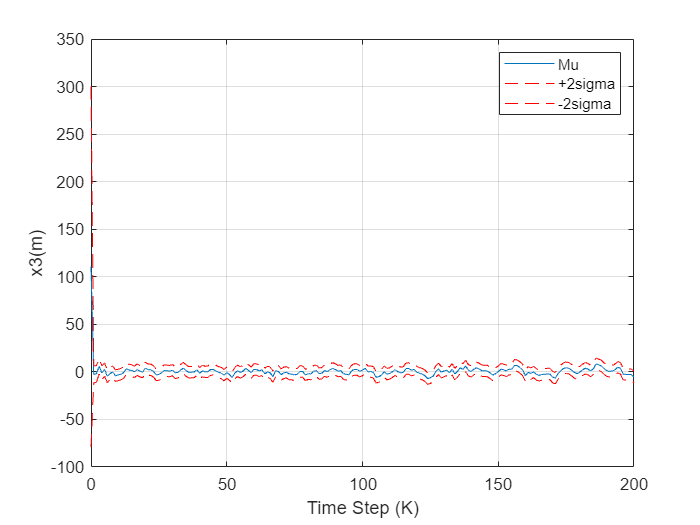

plot(time,x_err(3,:)),grid on,ylabel('x3(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p(3,:),'r--'),grid on
plot(time,sigma2n(3,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

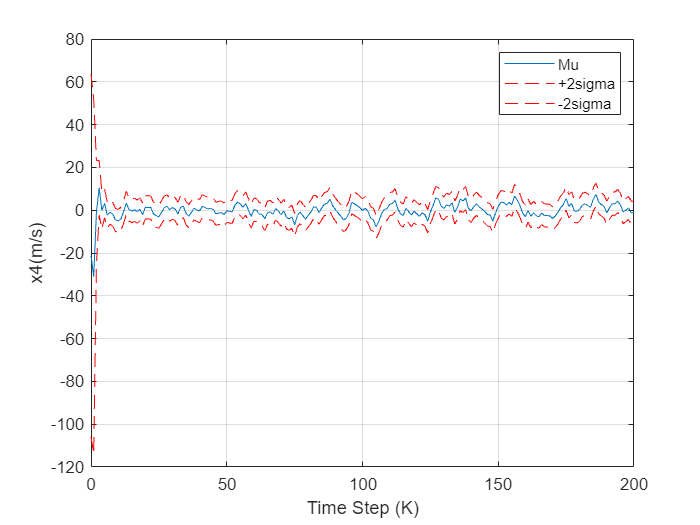

plot(time,x_err(4,:)),grid on,ylabel('x4(m/s)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p(4,:),'r--'),grid on
plot(time,sigma2n(4,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

Q2. B) The KF output for states X1 & X3 have more certanity than states X2 & X4 because it depends on the measurements y since we have measurements only for position, velocity propagates with just prediction, hence more uncertainity.

## Q3.A)

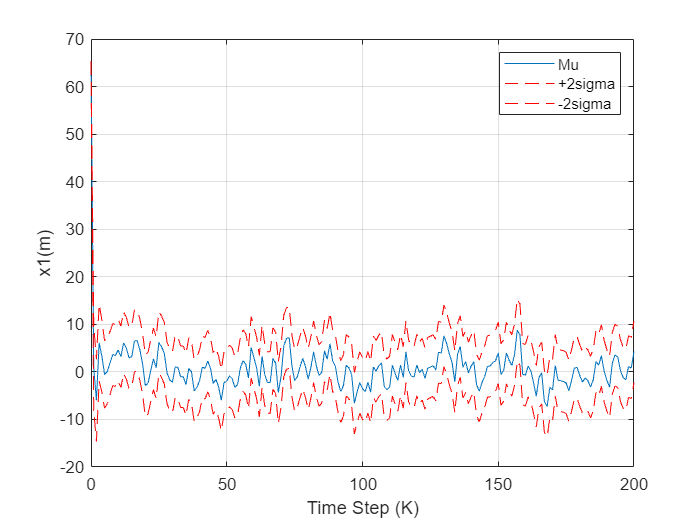

Ra = [20 0.05; 0.05 20];
Rd = [10 0.15; 0.15 10];

Hall = [H zeros(2,4); H -H];
R = [Ra zeros(2,2); zeros(2,2) Rd];
yd_k = [];
ya_new_k = [];

for n = 1:201
    yd = H*xadouble_truth(:,n) - H*xbdouble_truth(:,n) + (mvnrnd(zeros(2,1),Rd))';
    yd_k = [yd_k,yd];
    ya_new = H*xadouble_truth(:,n) + (mvnrnd(zeros(2,1),Ra))';
    ya_new_k = [ya_new_k,ya_new];
end

ys = vertcat(ya_new_k,yd_k);

% Kalman filtering
Mua0 = [0; 85*cos(pi/4); 0; -85*sin(pi/4)];
Pa0 = 900*diag([10,2,10,2]);
Mub0 = [3200; 85*cos(pi/4); 3200; -85*sin(pi/4)];
Pb0 = 900*diag([11,4,11,4]);
xa_all = zeros(4,201);
xa_all(:,1) = Mua0;
xb_all = zeros(4,201);
xb_all(:,1) = Mub0;
xs_all = vertcat(Mua0,Mub0);
Q_new = blkdiag(Qa,Qb);
P_new = blkdiag(Pa0,Pb0);
F_new = blkdiag(Fa,Fb);
H_new = [H zeros(2,4); H -H];

for k = 1:200
    % KF Time update
    xs_all(:,k+1) = F_new*xs_all(:,k);
    P_new = F_new*P_new*F_new'+ Q_new;
    Kk = P_new*H_new'*inv(H_new*P_new*H_new' + R);
    % KF Measurement update
    xs_all(:,k+1) = xs_all(:,k+1) + Kk*(ys(:,k+1)-H_new*xs_all(:,k+1));
    P_new = (eye(8,8) - Kk*H_new)*P_new;
    P_new_all(:,k+1) = diag(P_new);
end

P_new;
xs_all;
P_new_all;
xs_err = vertcat(xadouble_truth,xbdouble_truth) - xs_all;
sigma_s = sqrt(P_new_all);
sigma2p_s = xs_err + 2*sigma_s;
sigma2n_s = xs_err - 2*sigma_s;

time = 0:200;
plot(time,xs_err(1,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(1,:),'r--'),grid on
plot(time,sigma2n_s(1,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

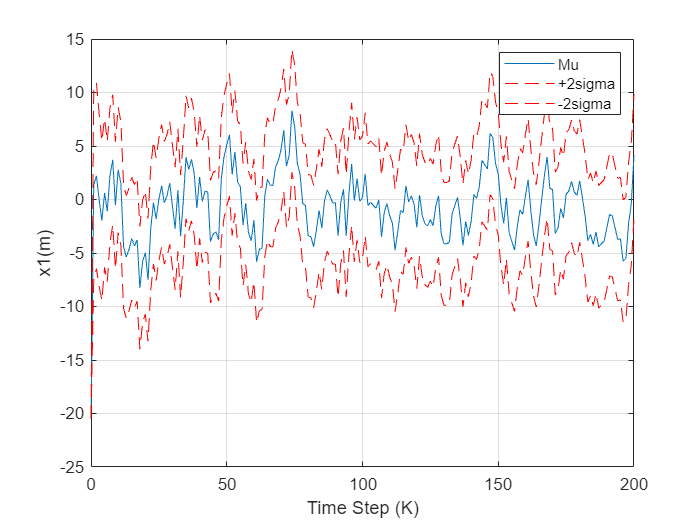

plot(time,xs_err(3,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(3,:),'r--'),grid on
plot(time,sigma2n_s(3,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

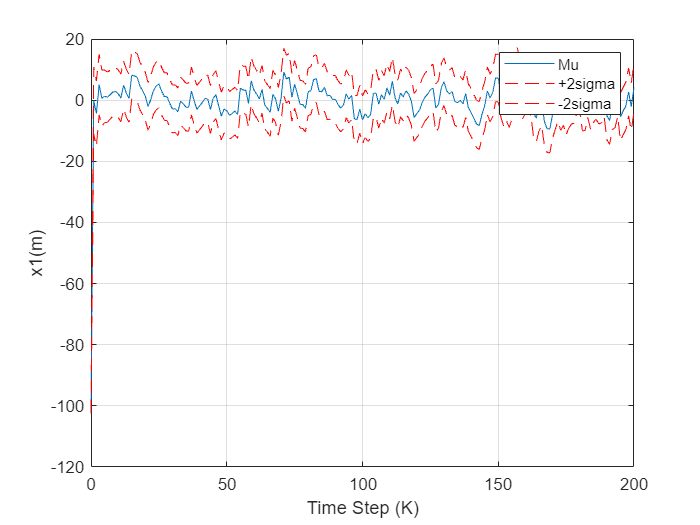

plot(time,xs_err(5,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(5,:),'r--'),grid on
plot(time,sigma2n_s(5,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

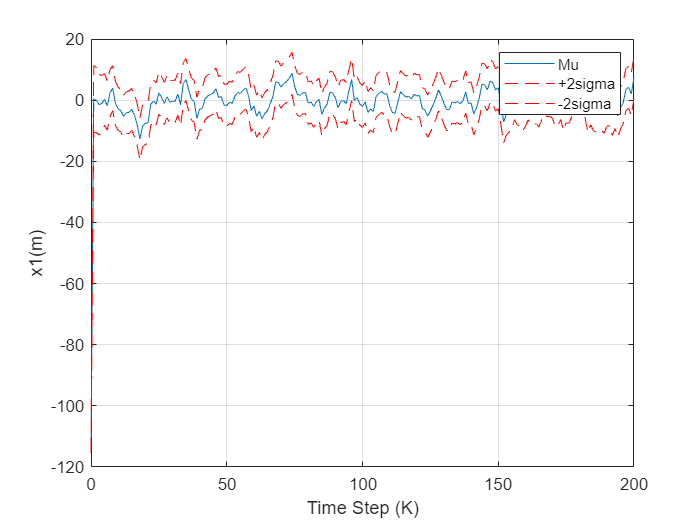

plot(time,xs_err(7,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(7,:),'r--'),grid on
plot(time,sigma2n_s(7,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

## Q3. B)

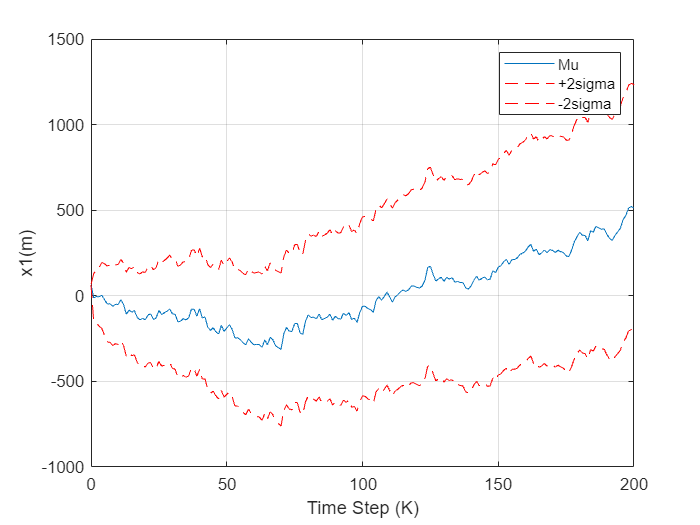

Rd = [10 0.15; 0.15 10];

Hd_all = [H -H];
yd_k = [];
ya_new_k = [];

for n = 1:201
    yd = H*xadouble_truth(:,n) - H*xbdouble_truth(:,n) + (mvnrnd(zeros(2,1),Rd))';
    yd_k = [yd_k,yd];
end

% Kalman filtering
Mua0 = [0; 85*cos(pi/4); 0; -85*sin(pi/4)];
Pa0 = 900*diag([10,2,10,2]);
Mub0 = [3200; 85*cos(pi/4); 3200; -85*sin(pi/4)];
Pb0 = 900*diag([11,4,11,4]);
xa_all = zeros(4,201);
xa_all(:,1) = Mua0;
xb_all = zeros(4,201);
xb_all(:,1) = Mub0;
xs_all = vertcat(Mua0,Mub0);
Q_new = blkdiag(Qa,Qb);
P_d = blkdiag(Pa0,Pb0);
F_new = blkdiag(Fa,Fb);

for k = 1:200
    % KF Time update
    xs_all(:,k+1) = F_new*xs_all(:,k);
    P_d = F_new*P_d*F_new'+ Q_new;
    Kk = P_d*Hd_all'*inv(Hd_all*P_d*Hd_all' + Rd);
    % KF Measurement update
    xs_all(:,k+1) = xs_all(:,k+1) + Kk*(yd_k(:,k+1)-Hd_all*xs_all(:,k+1));
    P_d = (eye(8,8) - Kk*Hd_all)*P_d;
    Pd_new_all(:,k+1) = diag(P_d);
end

P_d;
xs_all;
Pd_new_all;
xs_err = vertcat(xadouble_truth,xbdouble_truth) - xs_all;
sigma_s = sqrt(Pd_new_all);
sigma2p_s = xs_err + 2*sigma_s;
sigma2n_s = xs_err - 2*sigma_s;

time = 0:200;
plot(time,xs_err(1,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(1,:),'r--'),grid on
plot(time,sigma2n_s(1,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

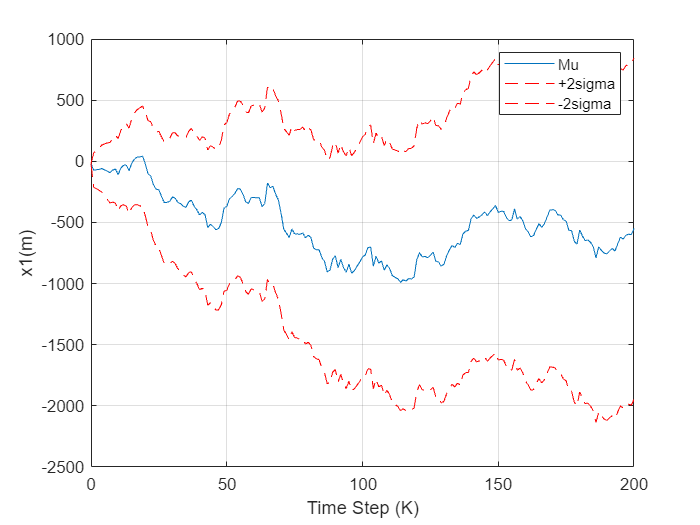

plot(time,xs_err(3,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(3,:),'r--'),grid on
plot(time,sigma2n_s(3,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

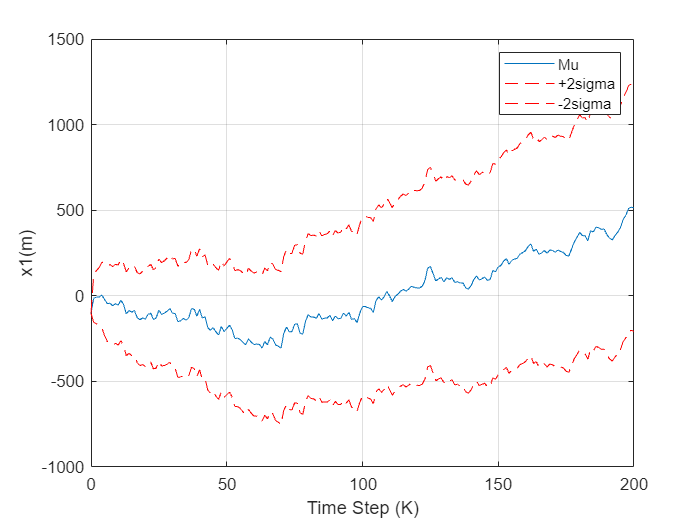

plot(time,xs_err(5,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(5,:),'r--'),grid on
plot(time,sigma2n_s(5,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

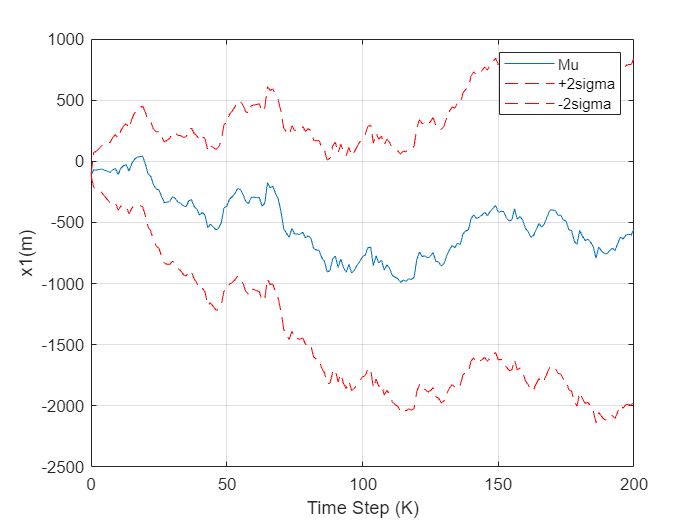

plot(time,xs_err(7,:)),grid on,ylabel('x1(m)'),xlabel("Time Step (K)")
hold on
plot(time,sigma2p_s(7,:),'r--'),grid on
plot(time,sigma2n_s(7,:),'r--'),grid on
legend("Mu","+2sigma","-2sigma")
hold off

Q3. B) In part A, we are using measurements Y(a) hence the error and sigma bounds are converging but in part B we have completely eliminated the true marusements the entire kalman filtering is done on pure prediction because of which the covariance matrix matrix keeps on increasing which in turn results in increasing error. Therefore the error ends up around 500 units and the bounds keep on divering.

## Q3. C)

for k = 1:200
    xs_all(:,k+1) = F_new*xs_all(:,k);
    P_new = F_new*P_new*F_new'+ Q_new;
    Ps_new (:,k+1) = diag(P_new);
end


xc_all = zeros(8,n);
xc_all(:,1) = [Mua0;Mub0];
Pc = blkdiag(Pa,Pb);
pcb2 = zeros(8,n);
pcb2(:,1) = diag(blkdiag(Pa,Pb));

for i= 1:n-1
    %prediction step
    xc_all(:,i+1) = F_new*xc_all(:,i);
    Pc = F_new*Pc*transpose(F_new) + Q_new;
    pcb2(:,i+1) = diag(Pc);
end

The structure of covariance matrix in part A differs from covariance matrix in part B because in part A we have correlation between flight A & flight B whereas in part B we do not have any correlation, hence, the covariance matrix sturcture is different.